close all; clear; clc;

# P80 30.5 inch prop 10-90 tests

**file name**: P80_305x97_1090_cont_varyBat.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p_jan17 = 0.002237827;                  %[slugs/ft^3]
p_jan18 = 0.002237589;
p_jan22 = 0.002226639;
p_jan23 = 0.002216009;
p_jan28 = 0.002212673;
p_jan29 = 0.002217501;

% Motor Specs
%radius_27x88 = 27 / 12 / 2;              % [ft] 
%area_27x88 = pi * 1.125^(2);             % [ft^2]
radius_305x97 = 30.5 / 12 / 2;           % [ft] 
area_305x97 = pi * radius_305x97^(2);    % [ft^2]

## Measured Data 1 battery Jan 22

load('P80_305x97_1b_1090_cont_1.mat');
time1 = P80_305x97_1b_1090_cont_1(:,1);                       % [sec]
PWM1 = P80_305x97_1b_1090_cont_1(:,2);                        % [micro sec]
Q1 = P80_305x97_1b_1090_cont_1(:,4);                          % [ft.lbf]
T1 = P80_305x97_1b_1090_cont_1(:,5);                          % [lbf]
Input_V1 = P80_305x97_1b_1090_cont_1(:,6);                    % [Volts]
Input_A1 = P80_305x97_1b_1090_cont_1(:,7);                    % [Amps]
rpm1 = P80_305x97_1b_1090_cont_1(:,8);                        % [RPM]
% convert to RPM for plotting purposes
rad1 = rpm1 .* (pi/30);                                       % [rad/sec]
P_in_W1 = P80_305x97_1b_1090_cont_1(:,9);                     % [Watts]
P_out_W1 = P80_305x97_1b_1090_cont_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out1 = P_out_W1 .* 0.7478;                                  % [ft.lbf/sec]         
P_in1 = P_in_W1 .* 0.7478;                                    % [ft.lbf/sec]
Motor_Eff1 = P80_305x97_1b_1090_cont_1(:,11);                 % [%]
Prop_Eff1 = P80_305x97_1b_1090_cont_1(:,12);                  % [lbf/Watts]
Overall_Eff1 = P80_305x97_1b_1090_cont_1(:,13);               % [lbf/Watts]  
ESC_Temp1 = P80_305x97_1b_1090_cont_1(:,14);                  % [F]
Motor_Temp1 = P80_305x97_1b_1090_cont_1(:,15);                % [F]
disk_loading1 = T1 ./ area_305x97;                             % [lb/sq.ft]]
throttle1 = (PWM1 - 1000) ./ 10;
ST1 = P80_305x97_1b_1090_cont_1(:,17);                        % [s]
Max_Acc1 = P80_305x97_1b_1090_cont_1(:,18);                   % [RPM]
C_T1 = T1 ./ (p_jan22 .* area_305x97 * (rad1 * radius_305x97).^2);
C_P1 = P_out1 ./ (p_jan22 .* area_305x97 .* (rad1 .* radius_305x97).^3);
C_Q1 = Q1 ./ (p_jan22 .* area_305x97 .* (rad1 .* radius_305x97).^(2) .* radius_305x97);

## Measured Data 2 bat Jan 23

load('P80_305x97_2b_1090_cont_1.mat');
time2 = P80_305x97_2b_1090_cont_1(:,1);                       % [sec]
PWM2 = P80_305x97_2b_1090_cont_1(:,2);                        % [micro sec]
Q2 = P80_305x97_2b_1090_cont_1(:,4);                          % [ft.lbf]
T2 = P80_305x97_2b_1090_cont_1(:,5);                          % [lbf]
Input_V2 = P80_305x97_2b_1090_cont_1(:,6);                    % [Volts]
Input_A2 = P80_305x97_2b_1090_cont_1(:,7);                    % [Amps]
rpm2 = P80_305x97_2b_1090_cont_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad2 = rpm2 .* (pi/30);   % [rad/sec]
P_in_W2 = P80_305x97_2b_1090_cont_1(:,9);                     % [Watts]
P_out_W2 = P80_305x97_2b_1090_cont_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out2 = P_out_W2 .* 0.7478;                  % [ft.lbf/sec]         
P_in2 = P_in_W2 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff2 = P80_305x97_2b_1090_cont_1(:,11);                 % [%]
Prop_Eff2 = P80_305x97_2b_1090_cont_1(:,12);                  % [lbf/Watts]
Overall_Eff2 = P80_305x97_2b_1090_cont_1(:,13);               % [lbf/Watts]  
ESC_Temp2 = P80_305x97_2b_1090_cont_1(:,14);                  % [F]
Motor_Temp2 = P80_305x97_2b_1090_cont_1(:,15);                % [F]
disk_loading2 = T2 ./ area_305x97;                     % [lb/sq.ft]]
throttle2 = (PWM2 - 1000) ./ 10;
ST2 = P80_305x97_2b_1090_cont_1(:,17); % [s]
Max_Acc2 = P80_305x97_2b_1090_cont_1(:,18);      % [RPM]
C_T2 = T2 ./ (p_jan23 .* area_305x97 * (rad2 * radius_305x97).^2);
C_P2 = P_out2 ./ (p_jan23 .* area_305x97 .* (rad2 .* radius_305x97).^3);
C_Q2 = Q2 ./ (p_jan23 .* area_305x97 .* (rad2 .* radius_305x97).^(2) .* radius_305x97);

## Measured Data 3 bat Jan 23

load('P80_305x97_3b_1090_cont_1.mat');
time3 = P80_305x97_3b_1090_cont_1(:,1);                       % [sec]
PWM3 = P80_305x97_3b_1090_cont_1(:,2);                        % [micro sec]
Q3 = P80_305x97_3b_1090_cont_1(:,4);                          % [ft.lbf]
T3 = P80_305x97_3b_1090_cont_1(:,5);                          % [lbf]
Input_V3 = P80_305x97_3b_1090_cont_1(:,6);                    % [Volts]
Input_A3 = P80_305x97_3b_1090_cont_1(:,7);                    % [Amps]
rpm3 = P80_305x97_3b_1090_cont_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad3 = rpm3 .* (pi/30);   % [rad/sec]
P_in_W3 = P80_305x97_3b_1090_cont_1(:,9);                     % [Watts]
P_out_W3 = P80_305x97_3b_1090_cont_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out3 = P_out_W3 .* 0.7478;                  % [ft.lbf/sec]         
P_in3 = P_in_W3 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff3 = P80_305x97_3b_1090_cont_1(:,11);                 % [%]
Prop_Eff3 = P80_305x97_3b_1090_cont_1(:,12);                  % [lbf/Watts]
Overall_Eff3 = P80_305x97_3b_1090_cont_1(:,13);               % [lbf/Watts]  
ESC_Temp3 = P80_305x97_3b_1090_cont_1(:,14);                  % [F]
Motor_Temp3 = P80_305x97_3b_1090_cont_1(:,15);                % [F]
disk_loading3 = T3 ./ area_305x97;                     % [lb/sq.ft]]
throttle3 = (PWM3 - 1000) ./ 10;
ST3 = P80_305x97_3b_1090_cont_1(:,17); % [s]
Max_Acc3 = P80_305x97_3b_1090_cont_1(:,18);      % [RPM]
C_T3 = T3 ./ (p_jan23 .* area_305x97 * (rad3 * radius_305x97).^2);
C_P3 = P_out3 ./ (p_jan23 .* area_305x97 .* (rad3 .* radius_305x97).^3);
C_Q3 = Q3 ./ (p_jan23 .* area_305x97 .* (rad3 .* radius_305x97).^(2) .* radius_305x97);

## Measured Data 4 batteries Jan 28

load('P80_305x97_4b_1090_cont_2.mat');
time4 = P80_305x97_4b_1090_cont_2(:,1);                       % [sec]
PWM4 = P80_305x97_4b_1090_cont_2(:,2);                        % [micro sec]
Q4 = P80_305x97_4b_1090_cont_2(:,4);                          % [ft.lbf]
T4 = P80_305x97_4b_1090_cont_2(:,5);                          % [lbf]
Input_V4 = P80_305x97_4b_1090_cont_2(:,6);                    % [Volts]
Input_A4 = P80_305x97_4b_1090_cont_2(:,7);                    % [Amps]
rpm4 = P80_305x97_4b_1090_cont_2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad4 = rpm4 .* (pi/30);   % [rad/sec]
P_in_W4 = P80_305x97_4b_1090_cont_2(:,9);                     % [Watts]
P_out_W4 = P80_305x97_4b_1090_cont_2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out4 = P_out_W4 .* 0.7478;                  % [ft.lbf/sec]         
P_in4 = P_in_W4 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff4 = P80_305x97_4b_1090_cont_2(:,11);                 % [%]
Prop_Eff4 = P80_305x97_4b_1090_cont_2(:,12);                  % [lbf/Watts]
Overall_Eff4 = P80_305x97_4b_1090_cont_2(:,13);               % [lbf/Watts]  
ESC_Temp4 = P80_305x97_4b_1090_cont_2(:,14);                  % [F]
Motor_Temp4 = P80_305x97_4b_1090_cont_2(:,15);                % [F]
disk_loading4 = T4 ./ area_305x97;                     % [lb/sq.ft]]
throttle4 = (PWM4 - 1000) ./ 10;
ST4 = P80_305x97_4b_1090_cont_2(:,17); % [s]
Max_Acc4 = P80_305x97_4b_1090_cont_2(:,18);      % [RPM]
C_T4 = T4 ./ (p_jan28 .* area_305x97 * (rad4 * radius_305x97).^2);
C_P4 = P_out4 ./ (p_jan28 .* area_305x97 .* (rad4 .* radius_305x97).^3);
C_Q4 = Q4 ./ (p_jan28 .* area_305x97 .* (rad4 .* radius_305x97).^(2) .* radius_305x97);

## Measured Data 5 batteries

load('P80_305x97_5b_1090_cont_1.mat');
time5 = P80_305x97_5b_1090_cont_1(:,1);                       % [sec]
PWM5 = P80_305x97_5b_1090_cont_1(:,2);                        % [micro sec]
Q5 = P80_305x97_5b_1090_cont_1(:,4);                          % [ft.lbf]
T5 = P80_305x97_5b_1090_cont_1(:,5);                          % [lbf]
Input_V5 = P80_305x97_5b_1090_cont_1(:,6);                    % [Volts]
Input_A5 = P80_305x97_5b_1090_cont_1(:,7);                    % [Amps]
rpm5 = P80_305x97_5b_1090_cont_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad5 = rpm5 .* (pi/30);   % [rad/sec]
P_in_W5 = P80_305x97_5b_1090_cont_1(:,9);                     % [Watts]
P_out_W5 = P80_305x97_5b_1090_cont_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out5 = P_out_W5 .* 0.7478;                  % [ft.lbf/sec]         
P_in5 = P_in_W5 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff5 = P80_305x97_5b_1090_cont_1(:,11);                 % [%]
Prop_Eff5 = P80_305x97_5b_1090_cont_1(:,12);                  % [lbf/Watts]
Overall_Eff5 = P80_305x97_5b_1090_cont_1(:,13);               % [lbf/Watts]  
ESC_Temp5 = P80_305x97_5b_1090_cont_1(:,14);                  % [F]
Motor_Temp5 = P80_305x97_5b_1090_cont_1(:,15);                % [F]
disk_loading5 = T5 ./ area_305x97;                     % [lb/sq.ft]]
throttle5 = (PWM5 - 1000) ./ 10;
ST5 = P80_305x97_5b_1090_cont_1(:,17); % [s]
Max_Acc5 = P80_305x97_5b_1090_cont_1(:,18);      % [RPM]
C_T5 = T5 ./ (p_jan28 .* area_305x97 * (rad5 * radius_305x97).^2);
C_P5 = P_out5 ./ (p_jan28 .* area_305x97 .* (rad5 .* radius_305x97).^3);
C_Q5 = Q5 ./ (p_jan28 .* area_305x97 .* (rad5 .* radius_305x97).^(2) .* radius_305x97);

## Plots

The following are standard charts. Remove, add, and edit as needed.

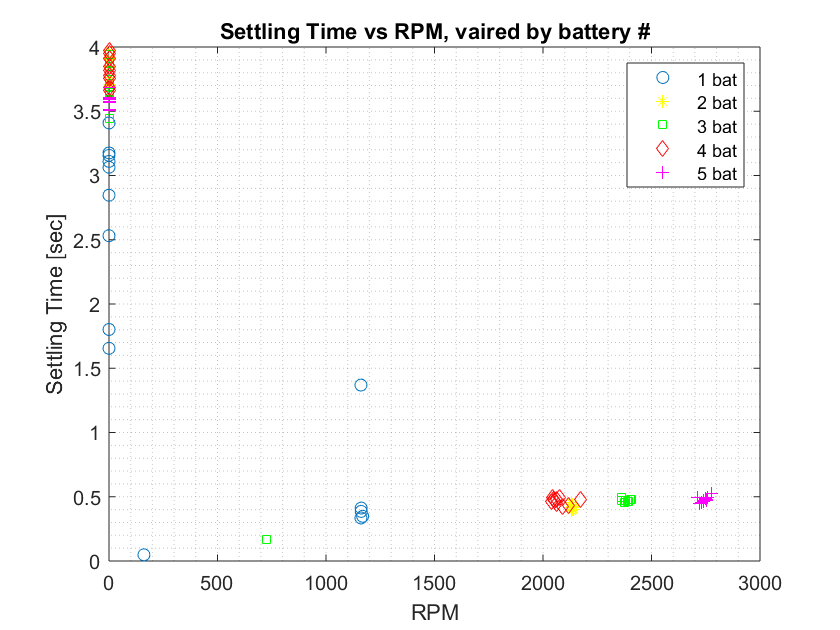

figure(1)
plot(rpm1, ST1, 'o',...
    rpm2, ST2, 'y*',...
    rpm3, ST3, 'gs',...
    rpm4, ST4, 'rd',...
    rpm5, ST5, 'm+');
grid('minor'); title('Settling Time vs RPM, vaired by battery #');
legend('1 bat', '2 bat', '3 bat', '4 bat', '5 bat');
ylabel('Settling Time [sec]'); xlabel('RPM');

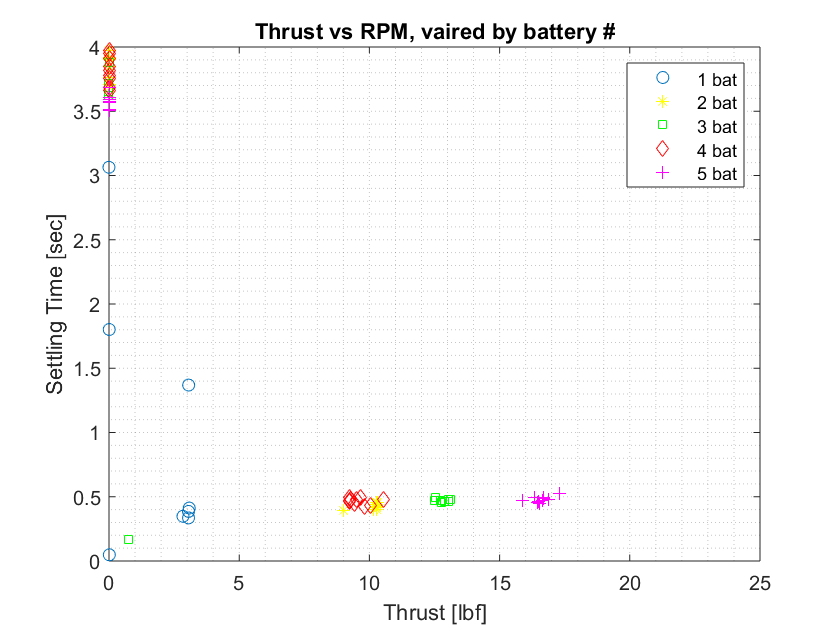


figure(2)
plot(T1, ST1,'o',...
    T2, ST2, 'y*', ...
    T3, ST3, 'gs', ...
    T4, ST4, 'rd',...
    T5, ST5, 'm+');
grid('minor'); title('Thrust vs RPM, vaired by battery #');
legend('1 bat', '2 bat', '3 bat', '4 bat', '5 bat');
ylabel('Settling Time [sec]'); xlabel('Thrust [lbf]');
xlim([0 25]);

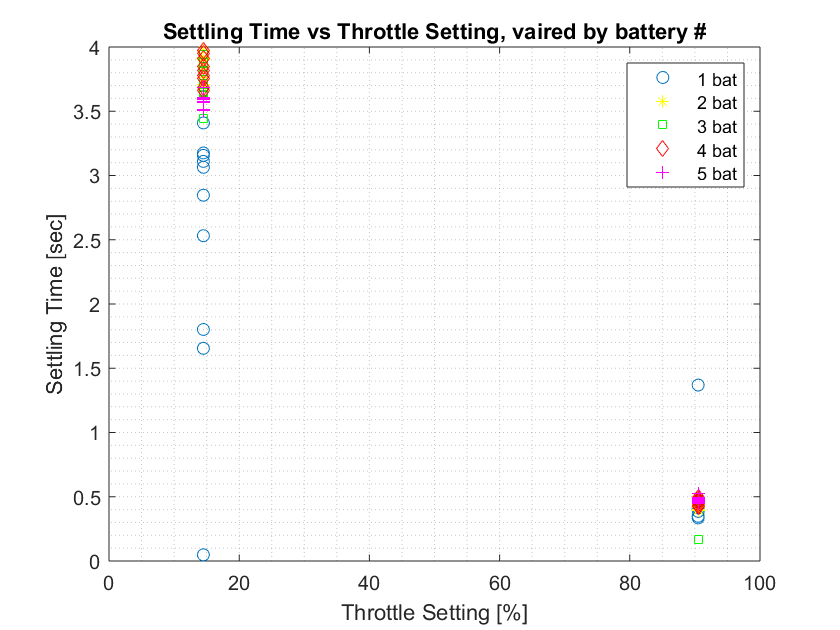


figure(3)
plot(throttle1, ST1, 'o',...
    throttle2, ST2, 'y*',...
    throttle3, ST3, 'gs',...
    throttle4, ST4, 'rd',...
    throttle5, ST5, 'm+');
grid('minor'); title('Settling Time vs Throttle Setting, vaired by battery #');
legend('1 bat', '2 bat', '3 bat', '4 bat', '5 bat');
ylabel('Settling Time [sec]'); xlabel('Throttle Setting [%]');
xlim([0 100]);

## Comparing Data to Momentum Theory

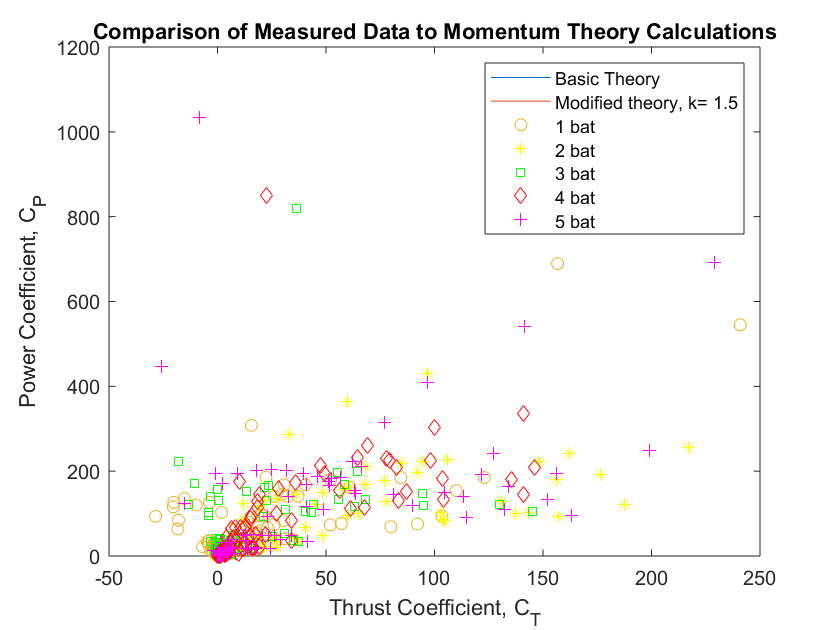

k = 1.15;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi,...
    C_T1, C_P1, 'o',...
    C_T2, C_P2, 'y*',...
    C_T3, C_P3, 'gs',...
    C_T4, C_P4, 'rd',...
    C_T5, C_P5, 'm+');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5',...
    '1 bat', '2 bat', '3 bat', '4 bat', '5 bat');